Companion software for "Volker Ziemann, *Hands-on Accelerator physics using MATLAB, CRCPress, 2019*" ([https://www.crcpress.com/9781138589940](https://www.crcpress.com/9781138589940))

# Super-conducting quadrupole (Section 4.4.2)

Volker Ziemann, 211110, CC-BY-SA-4.0

**Important:** this example requires the PDE toolbox!

In this example we prepare the coils of a super-conducting quadrupoles as four circle segments with 5 cm inner and 7 cm outer radius. The angular half-width can be adjusted with the variables` a`.  The coils are then included in a `World`, which defines the integration volume. 

clear all; close all
a=30;     % half the angular width of one segment
CS1=circlesegment(0.05,0.07,-a,a,10); nn=length(CS1);
CS2=circlesegment(0.05,0.07,90-a,90+a,10);
CS3=circlesegment(0.05,0.07,180-a,180+a,10);
CS4=circlesegment(0.05,0.07,270-a,270+a,10);
ws=0.2;
World=[2;4; -ws;ws;ws;-ws;-ws;-ws;ws;ws;zeros(nn-10,1)]; 

Now we assemble the geometry `g`, define the `model,` and attach the geometry to it...

gd=[World,CS1,CS2,CS3,CS4];  % assemble geometry
ns=char('World','CS1','CS2','CS3','CS4')';  % names of the regions                 
sf='World+CS1+CS2+CS3+CS4'; 
g=decsg(gd,sf,ns);
model=createpde(1);
geometryFromEdges(model,g);

...and display the` EdgeLabels` before defining the boundary conditions` u =` $A_z=0$ on the outer boundaries of the `World`. 

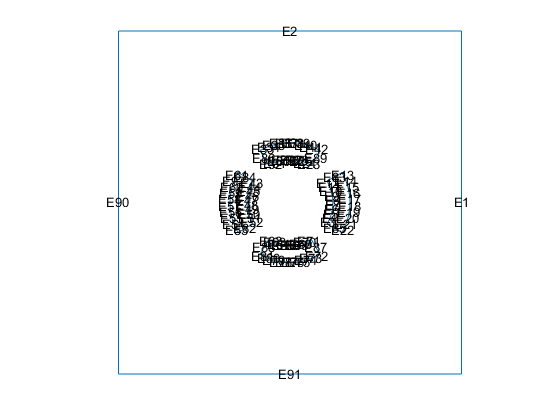

pdegplot(model,'EdgeLabels','on'); axis off; axis square;

applyBoundaryCondition(model,'Edge',[1,2,90,91],'u',0);
applyBoundaryCondition(model,'Edge',[1,2,90,91],'u',0);

Once we know the SubDomainLabels we can specify the material properties, where we choose a current density of 500 A/mm^2. In this view the geometry of the coils is obvious.

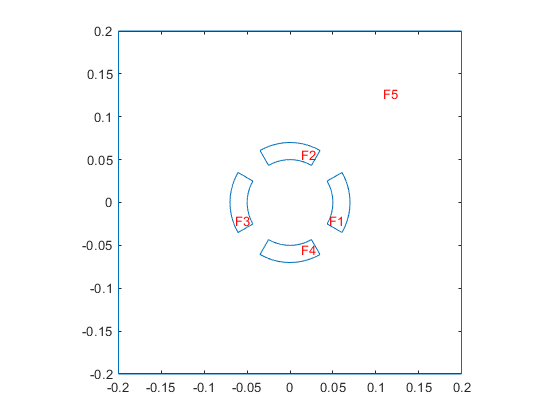

figure; pdegplot(model,'SubDomainLabels','on'); axis square;

specifyCoefficients(model,'m',0,'d',0,'c',1,'a',0,'f',628,'Face',[1,3]);
specifyCoefficients(model,'m',0,'d',0,'c',1,'a',0,'f',-628,'Face',[2,4]);
specifyCoefficients(model,'m',0,'d',0,'c',1,'a',0,'f',0,'Face',5);

Then we generate the mesh, display it and solve the problem with` solvepde()`, which returns the `result,` a structure whose member `NodalSolution` provides us the value of` u = `$A_z$ on the mesh points.

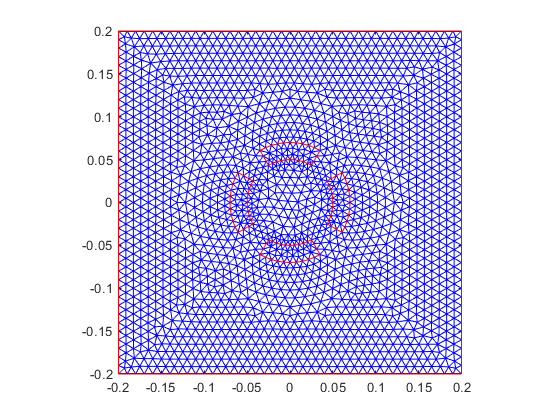

generateMesh(model,'Hmax',0.01);
figure; pdemesh(model); axis square;

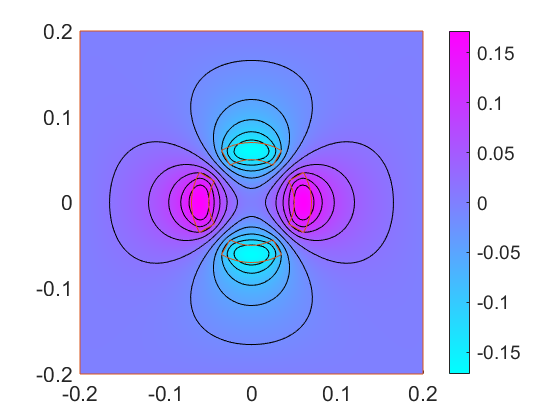

result=solvepde(model);
figure; pdeplot(model,'xydata',result.NodalSolution,'contour','on');
set(gca,'FontSize',16)
hold on; pdegplot(model)

As in previous examples we use the gradients to obtain the magnetic field components $B_x$ and $B_y$, which we plot them as arrows with `flowdata` and with `contour` lines and geometry superimposed.

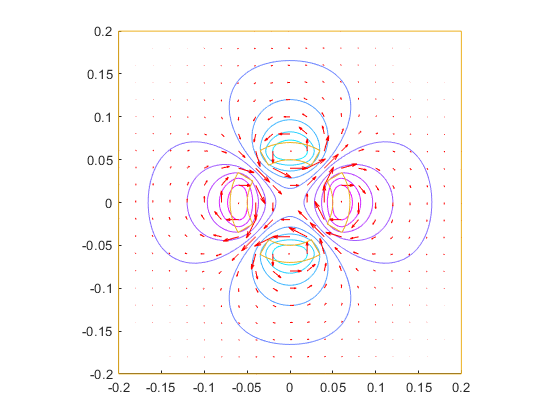


By=result.XGradients; Bx=-result.YGradients; 
figure; pdeplot(model,'xydata',result.NodalSolution,'xystyle','off', ...
  'flowdata',[Bx,By],'contour','on','colorbar','off'); axis square;
hold on; pdegplot(model);

Since the beam dynamics depends on the gradient of a quadrupole, we determine it by evaluating $B_y$ along a the horizontal axis in the range -4 cm < x < 4 cm. We find a rather linear dependence.

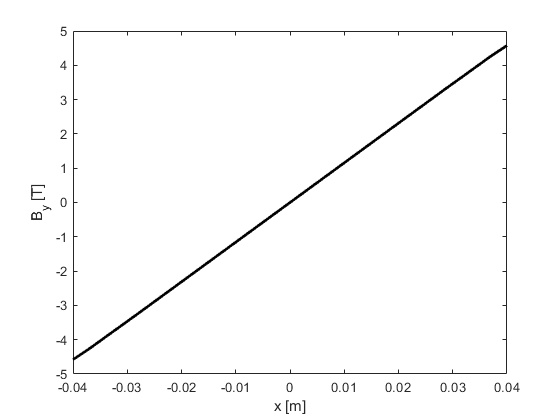

x=-0.04:0.001:0.04; y=zeros(1,length(x));
[By,Bx]=evaluateGradient(result,x,y);  Bx=-Bx;
figure; plot(x,By,'k','LineWidth',2);
xlabel('x [m]'); ylabel('B_y [T]')

And now explore! Maybe change the angular extent a of the coils, or simulate an error, such as one coil having moved by a small amount, either horizontally or vertically.

## Appendix

The function `circlesegment()` receives the following parameters as input

- `Ri`  = inner radius;

- `Ro` = outer radius;

- `phi1` = starting angle of the segment;

- `phi2` = ending angle of the segment;

- `N` = number of straight-line segment used to approximate the arcs;

It returns a column vector `cseg`  that describes a polygon describing the polygon. Inside the function *x*-ccordinates are calculated in the variables `xlist`, first on the inner radius and in the second loop over the outer radius.  Likewise contains `ylist` the *y*-coordinates. While calculating the points, the variable` ic` is incremented by one for each point. In the end a number 2, indicating a polygon , and the number of points `ic` is prepended to `xlist` and `ylist` and returned as `cseg`.

function cseg=circlesegment(Ri,Ro,phi1,phi2,N)
p1=phi1*pi/180; p2=phi2*pi/180;
dphi=(p2-p1)/N;
ic=0;
for k=0:N
  ic=ic+1;
  xlist(ic)=Ri*cos(p1+k*dphi); 
  ylist(ic)=Ri*sin(p1+k*dphi);
end
for k=0:N
  ic=ic+1;  
  xlist(ic)=Ro*cos(p2-k*dphi); 
  ylist(ic)=Ro*sin(p2-k*dphi);
end
cseg=[2;ic;xlist';ylist'];
end